
graphSet



filename = 'output'

filename = 'output'

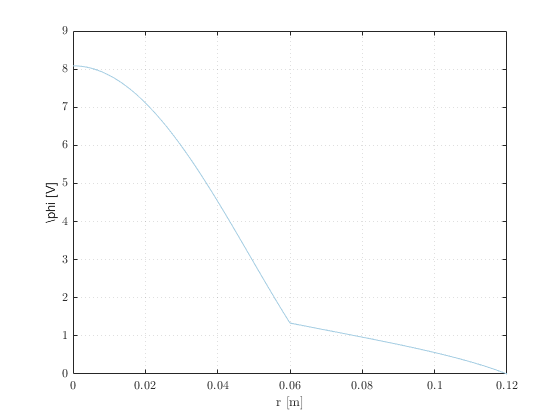


data = load([filename '_Er_Dr.out']);
rmid = data(:,1);
Er = data(:,2);
Dr = data(:,3);
data = load([filename '_phi.out']);
r = data(:,1);
phi = data(:,2);
data = load([filename '_rholib_divEr_divDr.out']);
rmidmid = data(:,1);
rholib = data(:,2);
divEr = data(:,3);
divDr = data(:,4);

figure
plot(r,phi)
xlabel('r [m]')
ylabel('\phi [V]')
grid on, box on

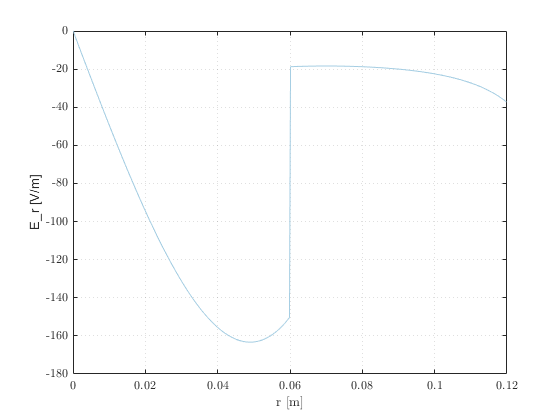


figure
hold on
plot(rmid,Er)
xlabel('r [m]')
ylabel('E_r [V/m]')
grid on, box on

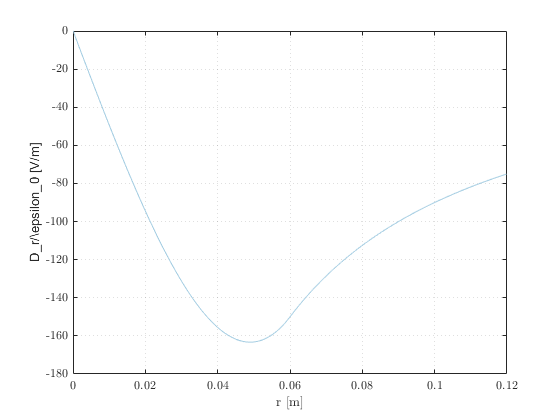


figure
hold on
plot(rmid,Dr)
xlabel('r [m]')
ylabel('D_r/\epsilon_0 [V/m]')
grid on, box on

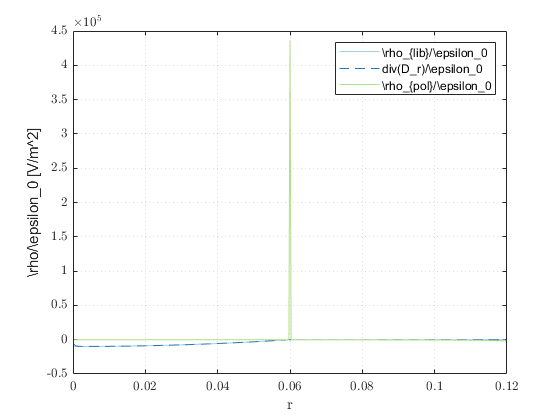


figure
hold on
plot(rmidmid,-rholib,'DisplayName','\rho_{lib}/\epsilon_0')
plot(rmidmid,divDr,'--','DisplayName','div(D_r)/\epsilon_0')
plot(rmidmid,divEr-divDr,'DisplayName','\rho_{pol}/\epsilon_0')
xlabel('r')
ylabel('\rho/\epsilon_0 [V/m^2]')
legend('show')
grid on, box on